# Zadatak1 - Estimacija trajanja reči i pitch periode govornika

## 1.0 - Snimanje sekvence

Fs = 8000; 
br_bita = 16;
br_kanala = 1;
audio_rec = audiorecorder(Fs, br_bita, br_kanala);
disp("Zapocnite govor.")

Zapocnite govor.



trajanje_sekvence = 8; 
recordblocking(audio_rec, trajanje_sekvence);
disp("Kraj snimanja.")

Kraj snimanja.



play(audio_rec);
sekvenca = getaudiodata(audio_rec);
fajl = 'govorna_sekvenca_Tpitch.wav';
audiowrite(fajl,sekvenca, Fs)

% [sekvenca, Fs] = audioread('sekvenca.wav');


## 1.1 - Estimacija trajanja reči

Prvi cilj ovog rada je odrediti početak i kraj reči svake od snimljenih reči unutar date sekvence. Od svih mogućih atributa signala koji nam mogu dati tu informaciju može se zaključiti da je kratkovremenska energija i kratkovremenska brzina prolaska kroz nulu pogodne za detekciju početka i kraja reči uprkos šumovitoj prirodi samog signala govora. Intuitivno to i ima smisla, s obzirom da očekujemo da imamo neko brdašce energije u nekom rasponu vremena trajanja same reči; dok brzina prolaska kroz nulu nam govori kada imamo taj neki bazni, spoljni gausovski šum. Detektovanje, ili segementacija samih reči se radi na osnovu praga

Treba napomenuti da kratkovremenski u ovom kontekstu se odnosi na prozorsku funkciju koja odabira i skalira određeni vremenski interval signala. Dalje su predstavljene definicije kratkovremenske energije i kratkovremenske brzine prolaska kroz nulu signala, respektivno: 


$$\textrm{STE}\left\lbrack n\right\rbrack =\sum_{k=-n+1}^N {x\left\lbrack n\right\rbrack }^2 h\left\lbrack n-k\right\rbrack$$



$$\textrm{STZOR}\left\lbrack n\right\rbrack =\frac{1}{N}\sum_{k=n+1}^N \frac{1}{2}\left|\textrm{sgn}\left(x\left\lbrack k\right\rbrack \right)-\textrm{sgn}\left(x\left\lbrack k-1\right\rbrack \right)\right|$$


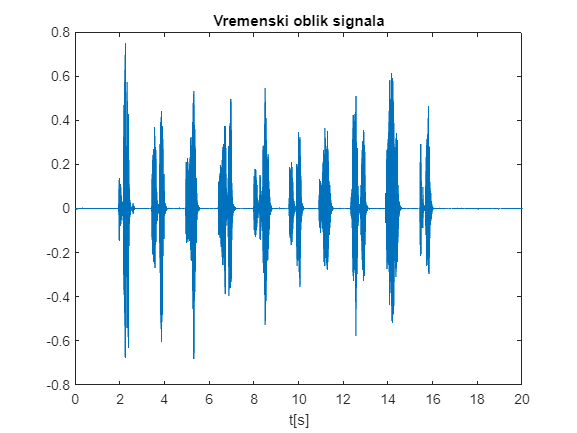


%Ucitavanje sekvence

[x, fs] = audioread('govorna_sekvenca.wav');

figure(1)
plot(1/fs:1/fs:length(x)/fs,x)
title('Vremenski oblik signala')
xlabel('t[s]')

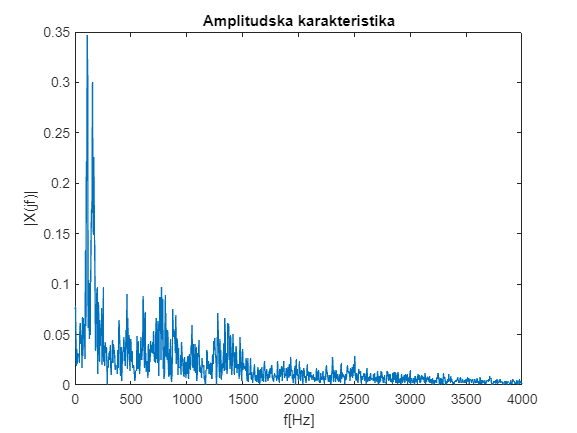


N = 2048;
X = fft(x,N);
Xa = abs(X(1:N/2+1));

figure(2)
plot(0:fs/N:fs/2,Xa)
xlabel('f[Hz]')
ylabel('|X(jf)|')
title('Amplitudska karakteristika')

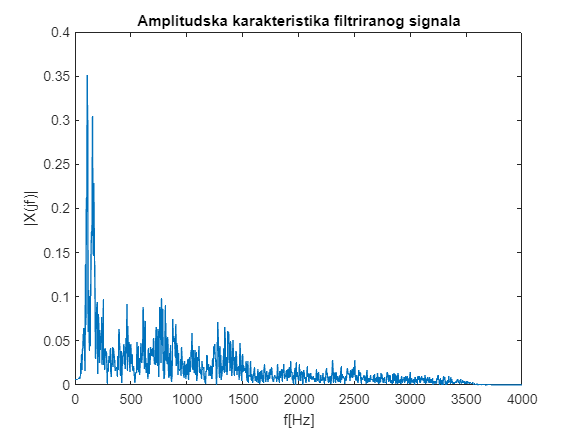


%% Filtriranje signala

Wn = [60 3500]/(fs/2); % fs/2 normalizacija zbog digitalnog filtra
[B,A] = butter(6,Wn,'bandpass');

xf = filter(B,A,x); % filtrirani signal

X = fft(xf,N);
Xf = abs(X(1:N/2+1));
figure(3)
plot(0:fs/N:fs/2,Xf)
xlabel('f[Hz]')
ylabel('|X(jf)|')
title('Amplitudska karakteristika filtriranog signala')

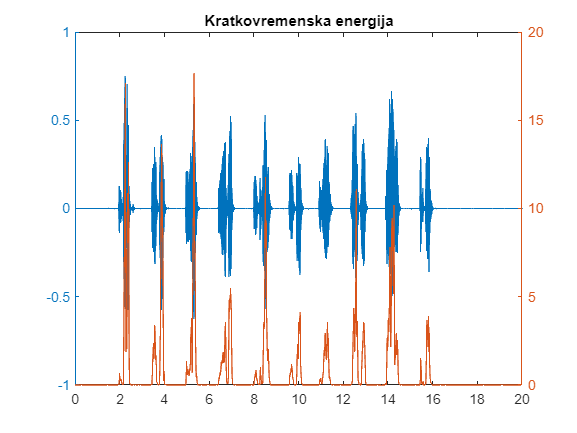

wl = 20e-3*fs;

E = zeros(size(xf)); % KVE - kratkovremenska energija
Z = zeros(size(xf)); % ZCR - zero crossing rate
for i = wl:length(xf)
    rng = (i - wl + 1):i-1;
    E(i) = sum(xf(rng).^2);
    Z(i) = sum(abs(sign(xf(rng + 1)) - sign(xf(rng))));
end

Z = Z/wl/2;
time = 1/fs:1/fs:length(E)/fs;

figure(5)
plotyy(time,xf,time,E)
title('Kratkovremenska energija')

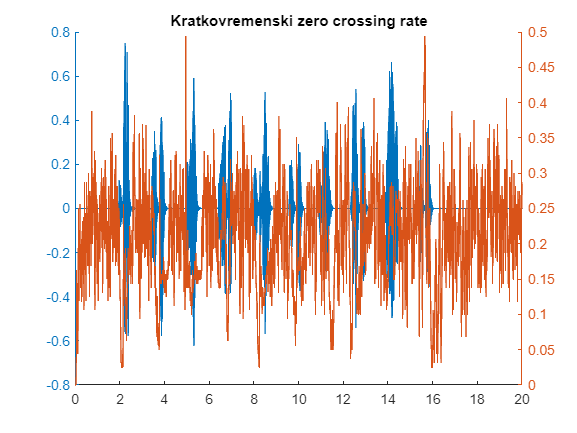


figure(6)
plotyy(time,xf,time,Z)
title('Kratkovremenski zero crossing rate')

Bitno je iskomentarisati dati proces segementacije. Ranije je predočeno da su nam bitni segmenti kratkovremenske energije koji čine neku vrstu grupacije, "brda". Centar tih brda se nalaze sa samo gornjim pragom; što čini inicijalnu segmentaciju. Širina brdašca se dobija tako što se inicijalna segmentacija širi i zauzima iterativno odbirke dokle god je kratkotrajna energija manja veća od donjeg praga. Što čini drugi korak segmentacije reči. Prema dobijenim rezultatima može se zaključiti da je ovaj proces itekako zadovoljavajuć.

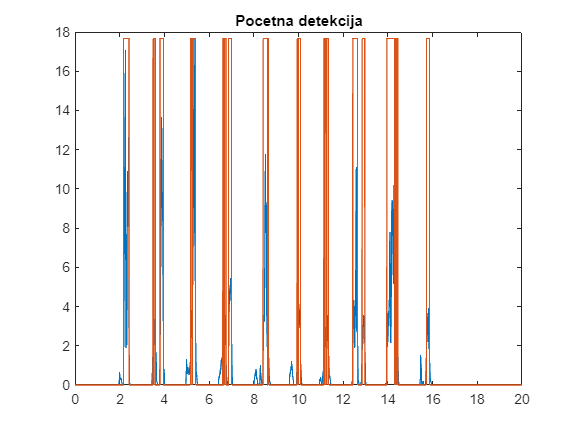



% Segmentacija

ITU = 0.1*max(E);
ITL = 0.0001*max(E);

% pravimo niz pocetaka i kraja reci

pocetak = [];
kraj = [];

% poredjenje sa vecim pragom ITU
for i = 2:length(E)
    if E(i) > ITU && E(i-1) < ITU
        pocetak = [pocetak i];
    end
    if E(i) < ITU && E(i-1) > ITU
        kraj = [kraj i];
    end
end

rec = zeros(1,length(E));

for i = 1:length(pocetak)
    rec(pocetak(i):kraj(i)) = max(E);
end

figure(7)
plot(time,E,time,rec)
title('Pocetna detekcija') % poredjenje samo sa vecim pragom ITU

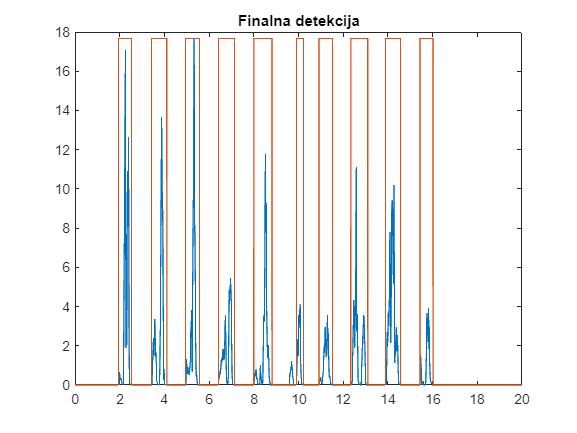


% vidimo da su detektovane 3 reci, a slusanjem zakljucujemo da su u pitanju
% 2 reci

for i = 1:length(pocetak)
    pomeraj = pocetak(i);
    while E(pomeraj)>ITL
        pomeraj = pomeraj - 1;
    end
    pocetak(i) = pomeraj; % azuriramo pocetak reci
end

for i = 1:length(kraj)
    pomeraj = kraj(i);
    while E(pomeraj)>ITL
        pomeraj = pomeraj + 1;
    end
    kraj(i) = pomeraj; % azuriramo pocetak reci
end

% uklanjanje duplikata (sada smo spojili dve reci tako sto one imaju isti
% pocetak i kraj, ali oni su duplikati)

pocetak = unique(pocetak);
kraj = unique(kraj);

rec = zeros(1,length(E));

for i = 1:length(pocetak)
    rec(pocetak(i):kraj(i)) = max(E);
end

figure(8)
plot(time,E,time,rec)
title('Finalna detekcija') % nakon poredjenja sa nizim pragom ITL


%% Preslusavanje reci

for i = 1:length(pocetak)
    sound(xf(pocetak(i):kraj(i)),fs);
    pause()   
end


## 1.2 - Estimacija pitch periode

Pitch perioda predstavlja periodu oscilacija glasnih žica govornika - periodičnu pobudu. Projektant je odlučio da koristi reči sa puno samoglasnika radi većeg udela signala same pitch periode u "sirovom" signalu. Biće korišćene dve metode za estimaciju pitch periode signala; metod paralelnog procesiranja i autokorelaciona metoda.

Metod paralelnog procesiranja funkcioniše tako što se formira šest impulsa na osnovu lokalnih minimuma i maksimuma datog signala, što u neku ruku ima smisla. Potrebno je izvući informaciju o sporopromenljivom nosećem signalu same pobude, što se može izvući iz specifičnih kombinacija ekstrema samog signala. Te povorke impulsa ulaze u dalju obradu gde se nakon određenog blanking perioda traži presek opadajuće eksponencijalne funkcije i narednog impulsa u datoj povorci impulsa, čime se određuje jedna procena pitch periode. Za konačnu estimaciju se uzima i prethodna vrednost estimacije pitch periode uz novodobijenih šest estimacija pitch periode, gde se za konačnu estimaciju obično primenjuje medijanski estimator. 

Autokorelacioni metod se zasniva na činjenici da ukoliko je signal $x\left\lbrack n\right\rbrack$ periodičan sa periodom $P$*,* sledi i da će autokoeralcija $R_{\textrm{xx}}$, biti periodična sa periodom $P\ldotp$ U literaturi se obično primenjuje i nelinearna transformacija signala(kliping), da bi se poboljšala estimacija pitch periode.

### 1.2.1 - Metoda paralelnog procesiranja

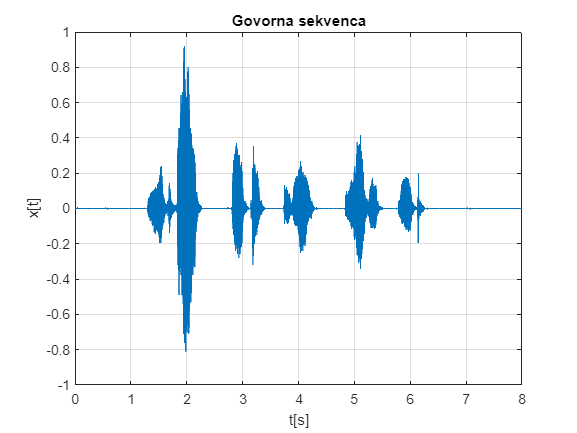


% Ucitavanje sekvence

[x, fs] = audioread('govorna_sekvenca_Tpitch.wav');
figure()
plot(0:1/fs:(length(x)-1)/fs,x);
title('Govorna sekvenca');
xlabel('t[s]'); ylabel('x[t]'); grid on;

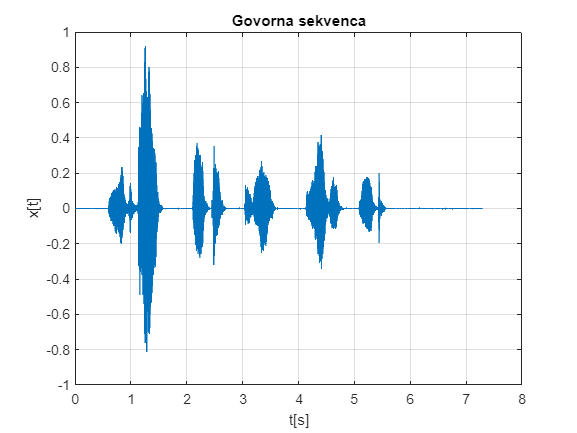


%% Grubo odsecanje tisine

start_time = 0.7*fs;
x = x(start_time:end);
figure()
plot(0:1/fs:(length(x)-1)/fs,x);
title('Govorna sekvenca');
xlabel('t[s]'); ylabel('x[t]'); grid on;

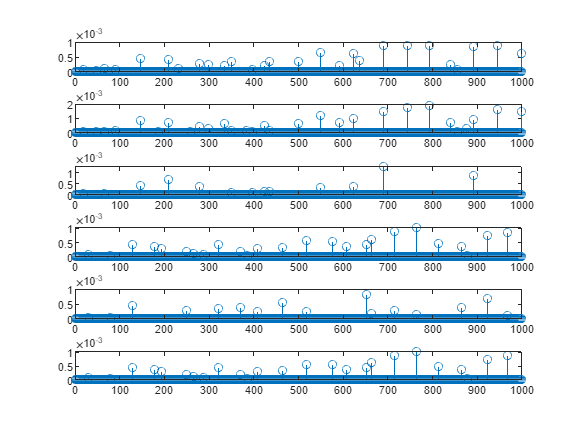


%% Filtriranje - bitno je da lepo isfiltriramo za dobre rezultate

Wn = [90 450]/(fs/2); % normalizujemo!
[B, A] = butter(6,Wn,'bandpass');
x = filter(B,A,x);

%% Pravljenje sekvenci (m1, ... m6)
[m1, m2, m3, m4, m5, m6] = sekvence(x);
figure()
subplot(611)
stem(m1(1:1000));
subplot(612)
stem(m2(1:1000));
subplot(613)
stem(m3(1:1000));
subplot(614)
stem(m4(1:1000));
subplot(615)
stem(m5(1:1000));
subplot(616)
stem(m6(1:1000));

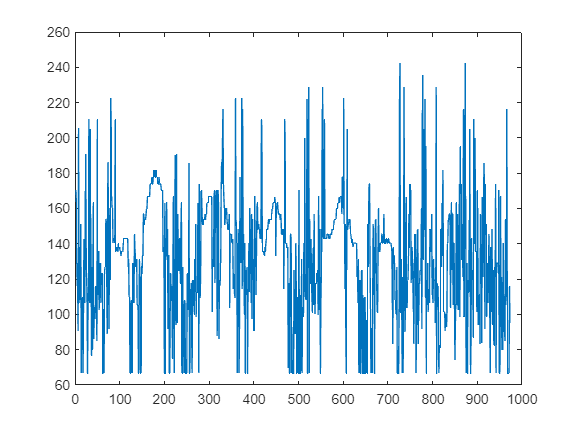


%% Procena pitch frekvencije

N = length(x);
[pt1, pt2, pt3, pt4, pt5, pt6, pt] = procena_periode(fs, N, m1, m2, m3, m4, m5, m6);
figure()
plot(1./pt)

Procenjena frekvencija glasa i jeste u teorijskom rangu koji je predvidjen za muskarca. Postoji određena šumovistost dobijene estimacije, što bi potencijalno moglo da se otkloni sa dužim trajanjem blanking periode.

### 1.2.2 - Autokorelaciona metoda

% Ucitavanje sekvence

[x, fs] = audioread('govorna_sekvenca_Tpitch.wav');
figure()
plot(0:1/fs:(length(x)-1)/fs,x);
title('Govorna sekvenca');
xlabel('t[s]'); ylabel('x[t]'); grid on;


%% Grubo odsecanje tisine

start_time = 0.7*fs;
x = x(start_time:end);
figure()
plot(0:1/fs:(length(x)-1)/fs,x);
title('Govorna sekvenca');
xlabel('t[s]'); ylabel('x[t]'); grid on;


%% Filtriranje - bitno je da lepo isfiltriramo za dobre rezultate

Wn = [90 450]/(fs/2); % normalizujemo!
[B, A] = butter(6,Wn,'bandpass');
x = filter(B,A,x);

Racunanje autokorelacije:

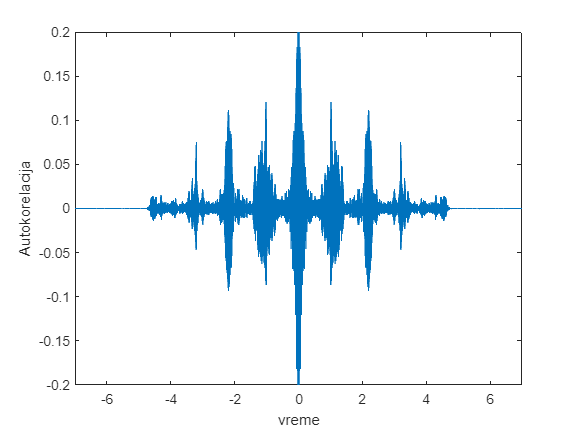


[autocor,lags] = xcorr(x,3*7*fs,'coeff');

plot(lags/fs,autocor)
xlabel('vreme')
ylabel('Autokorelacija')
axis([-7 7 -0.2 0.2])

Posmatrajući dobijenu funckiju autokorelacije i traženjem prosečnog rastojanja u lokacijama peakova funkcije može se izvući periodičnost dela signala koje sačinjavaju same reči. Zatim se ta vrednost u broju odbiraka množi sa $\frac{1}{\textrm{fs}}$; što proizilazi is teorijskih razmatranja o obliku autokorelacione funkcije periodičnog signala. Dobijena vrednost pitch periode nije baš zadovoljavajuća, ali je barem u redu veličine očekivane vrednosti za pitch periodu. Treba obraditi pažnju na koji način obrađujemo autokorelacionu funkciju, s obzirom da autokorelaciona funkcija "vadi" sve moguće periodičnosti signala; zbog čega i jeste koristan alat za analize periodičnosti signala. 

[pksh,lcsh] = findpeaks(autocor);
T_pitch = mean(diff(lcsh))/fs

T_pitch = 0.0033

Bonus: Periodičnost same povorke reči

[pklg,lclg] = findpeaks(autocor, ...
    'MinPeakDistance',ceil(short)*fs,'MinPeakheight',0.05);
long = mean(diff(lclg))/fs

long = 1.0673